f = 500 % Frequency in MHz

f = 500

lambda = 300/f

lambda = 0.6000


Rpu = 1

Rpu = 1

c = 0.01:0.001:5;
Rsu = c .* Rpu;
Psu = 500

Psu = 500

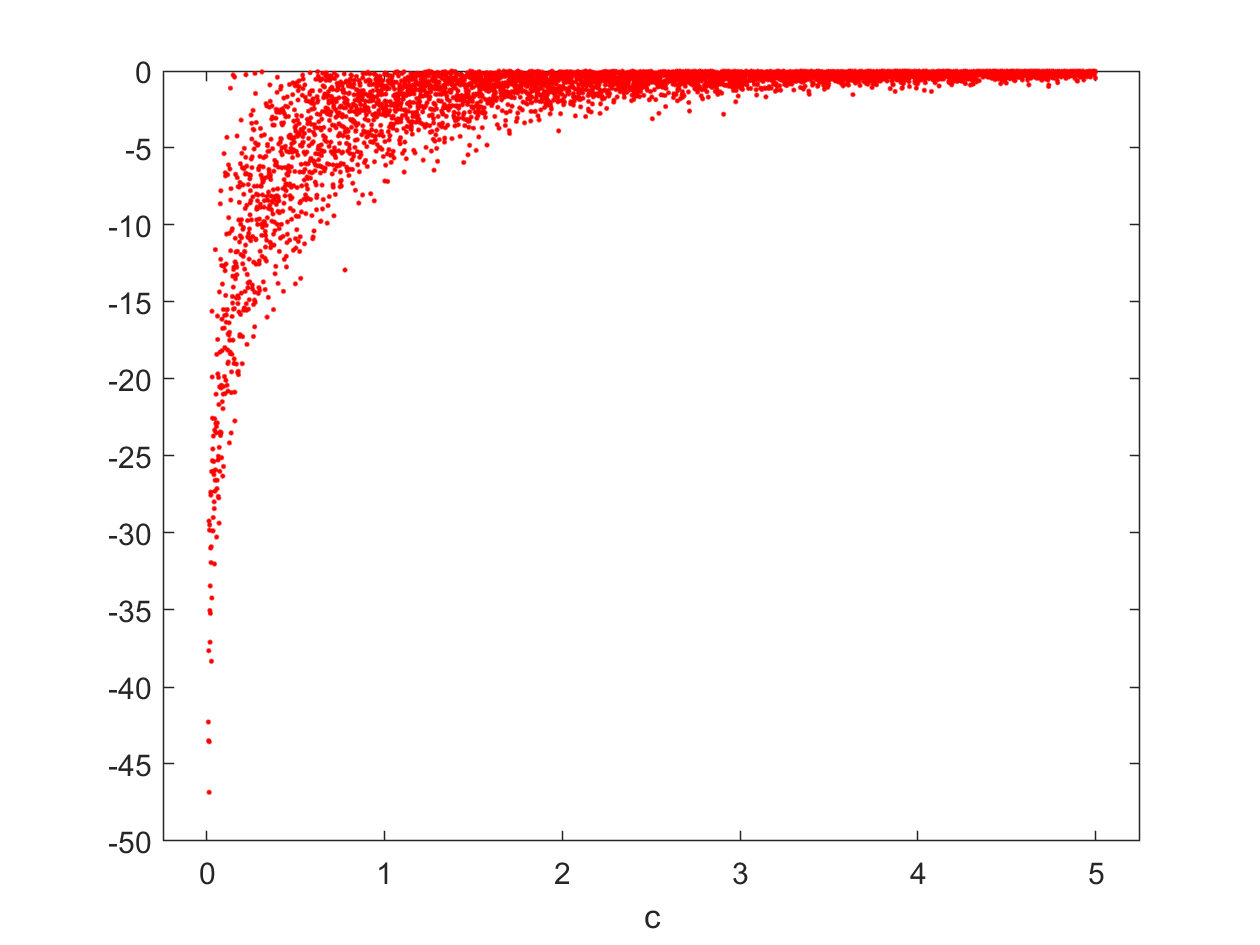

SNR = zeros(1,length(c));


for i = 1:length(c)
    a = (2/pi) * raylrnd(1);
    a = a^2;
    PLsu = (lambda / (4*pi*Rsu(i)))^2;
    SNR(i) = 1 / (1 + PLsu * a * Psu);
end

gscatter(c, 10*log10(SNR))

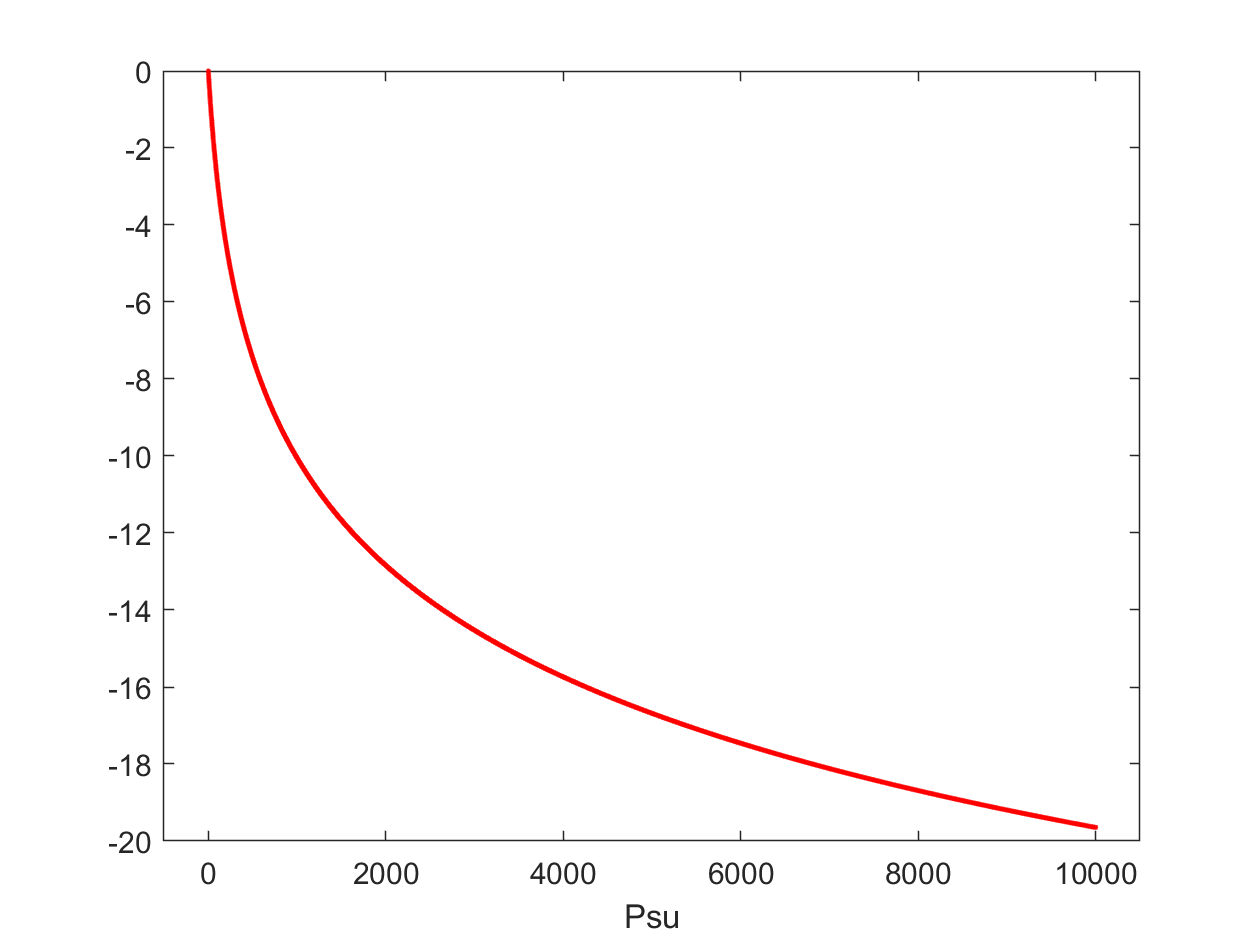



% SU Power dependence of SNR


Rpu = 1;
Rsu = 0.5;
Psu = 0:1:10000;
SNR = zeros(1,length(Psu));
for i = 1:length(SNR)
%     a = (2/pi) * raylrnd(1);
    a = 1;
    a = a^2;
    PLsu = (lambda / (4*pi*Rsu))^2;
    SNR(i) = 1 / (1 + PLsu * a * Psu(i));
end

gscatter(Psu, 10*log10(SNR))

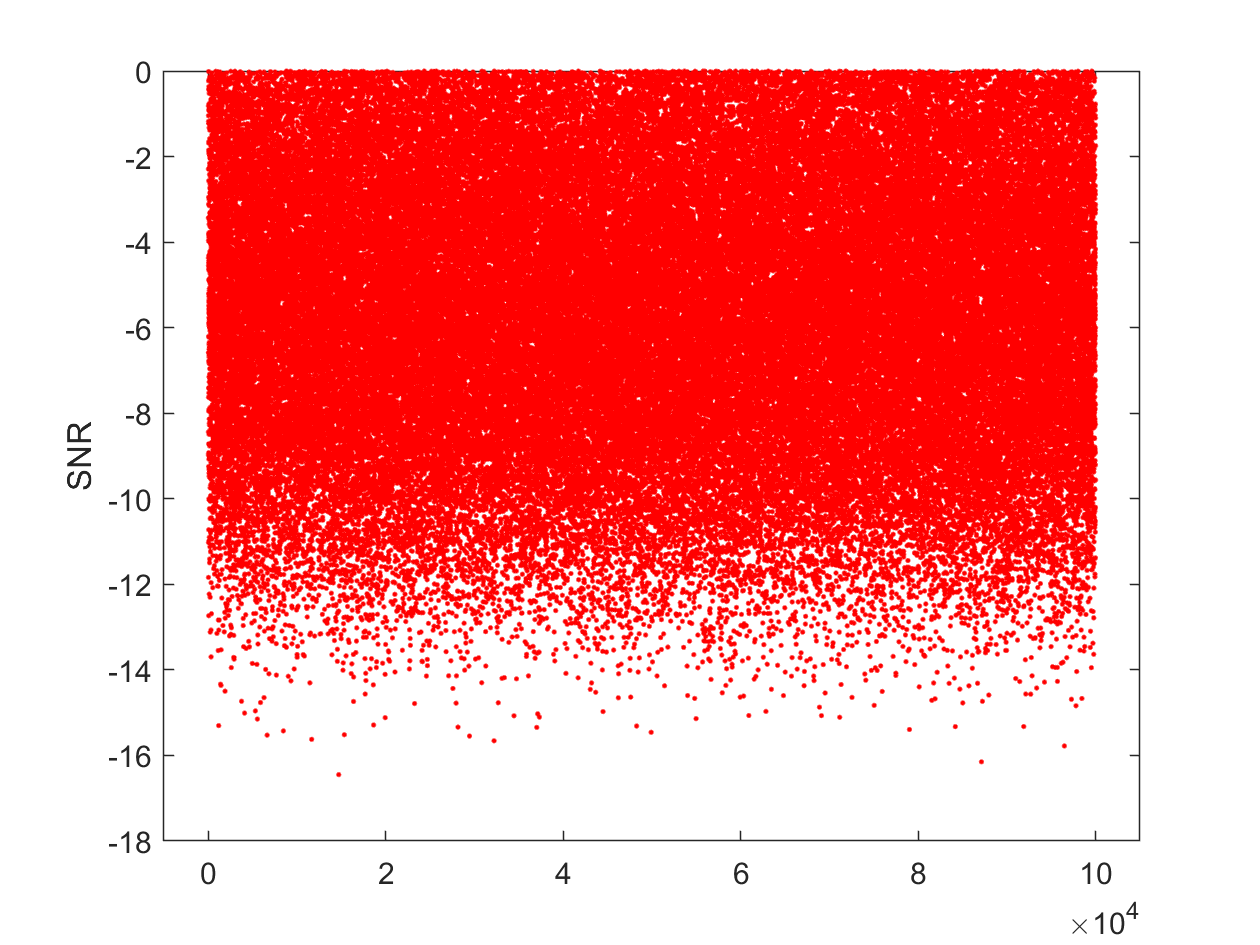



% Outage Probability

Rpu = 1;
Rsu = 0.5;
Psu = 500;
testSamples = 100000;
SNR = zeros(1,testSamples);

for i = 1:testSamples
    a = (2/pi) * raylrnd(1);
    a = a^2;
    PLsu = (lambda / (4*pi*Rsu))^2;
    SNR(i) = 1 / (1 + PLsu * a * Psu);
end
SNR = 10*log10(SNR);
gscatter(1:testSamples,SNR)

mean(SNR)

ans = -5.5977

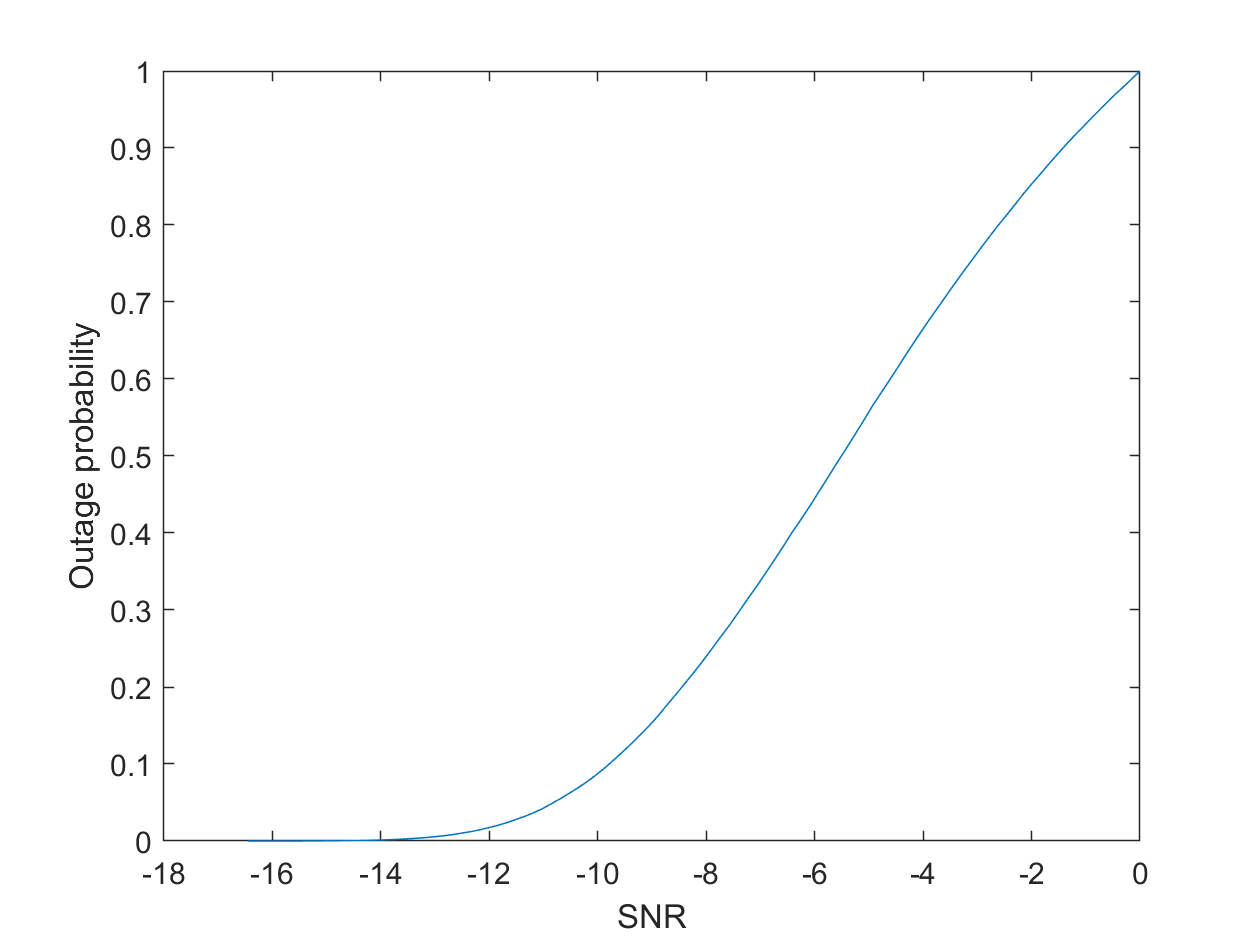


k = min(SNR);
g = max(SNR);

gamma = k: (g-k) / 100 : g;
F = zeros(1,length(gamma));

for i = 1:length(gamma)
    F(i) = length(find(SNR < gamma(i)))/testSamples;
end

plot(gamma, F)


Rate = log2(1+10^(mean(SNR)/10))

Rate = 0.3511


% % Use of knowledge extracted by Spectrum Sensing
% 
% Rpu = 1;
% Rsu = 0.5;
% 
% % Create probabilities
% 
% Samples = 1000000;
% lower = 0;
% upper = 100;
% scenario = [0, 1];
% prediction = zeros(1, Samples);
% 
% r = (upper-lower).*rand(Samples,1) + lower;
% l = 100 - r;
% b = ~(r > 50);
% 
% % for i = 1:Samples
% %     prediction(i) = randsample(scenario, 1, true, [r(i)/100, l(i)/100]);
% % end
% 
% t = 1;
% for Accuracy = 0.75:0.01:1
%     
%     for i = 1:Samples
%         prediction(i) = randsample([b(i), ~b(i)], 1, true, [Accuracy, 1-Accuracy]);
%     end
%     
%     p = [r, l, b, prediction'];
%     
%     P1 = 500;
%     P2 = 2000;
%     Rsu = 0.5;
%     PLsu = (lambda / (4*pi*Rsu))^2;
%     
%     
%     for i = 1:Samples
%         
%         h = (2/pi) * raylrnd(1);
%         h = h^2;
%         
%         if(p(i,3))
%             P = P1;
%         else
%             P = P2;
%         end
%         
%         if(p(i,4))
%             PU_SNR(i) = 1 / (1 + h * PLsu * P);
%         else
%             PU_SNR(i) = 0;
%         end
%         
%     end
%     
%     b_SNR = PU_SNR(find(PU_SNR ~= 0));
%     b_mean(t) = mean(10*log10(b_SNR));
%     b_rate(t) = log2(1+10^(b_mean(t)/10));
%     
%     % Use of knowledge extracted by Spectrum Sensing but with dynamic
%     % production of SU Tx power
%     
%     
%     for i = 1:Samples
%         
%         h = (2/pi) * raylrnd(1);
%         h = h^2;
%         
%         if(p(i,3))
%             P = P1;
%         else
%             P = 3000 * r(i)/100 - 1000;
%         end
%         
%         if(p(i,4))
%             dyn_PU_SNR(i) = 1 / (1 + h * PLsu * P);
%         else
%             dyn_PU_SNR(i) = 0;
%         end
%         
%     end
%     
%     dyn_SNR = dyn_PU_SNR(find(dyn_PU_SNR ~= 0));
%     dyn_mean(t) = mean(10*log10(dyn_SNR));
%     dyn_rate(t) = log2(1+10^(dyn_mean(t)/10));
%     t = t + 1;
%     
% end
% 
% figure
% plot(0.75:0.01:1,b_mean)
% hold on
% plot(0.75:0.01:1, dyn_mean)
% 
% figure
% plot(0.75:0.01:1,b_rate)
% hold on
% plot(0.75:0.01:1, dyn_rate)